%% Endast Metod 2 + RBF SVM + Rotation Augmentation (CAPTCHA)
% Fast segmentering (4 lika delar) + HOG/pixelfeatures + RBF-SVM
% Augmentation: original + 4 roterade versioner per bild (max ±15°)

clear; clc;

%% 0) Sökväg
trainPath = 'C:\Users\dbvol\MATLAB Drive\IIA_group_13\Train';

%% 1) Läs labels.txt
fid = fopen(fullfile(trainPath, 'labels.txt'), 'r');
if fid == -1
    error('Kunde inte öppna labels.txt');
end
labelData = textscan(fid, '%s', 'Delimiter', '\n');
fclose(fid);
labelData = labelData{1};

%% 2) Ladda bilder + labels
allImages = {};
allLabels = {};

for i = 1:length(labelData)
    line = strtrim(labelData{i});
    if isempty(line), continue; end

    parts = strsplit(line, ',');
    if numel(parts) >= 5
        fileNum = strtrim(parts{1});
        digits = strcat(strtrim(parts{2}), strtrim(parts{3}), strtrim(parts{4}), strtrim(parts{5}));
        filename = sprintf('captcha_%s.png', fileNum);

        imgPath = fullfile(trainPath, filename);
        if exist(imgPath, 'file')
            allImages{end+1} = imread(imgPath);
            allLabels{end+1} = digits;
        end
    end
end

fprintf('Laddade %d bilder\n', numel(allLabels));

Laddade 1200 bilder



%% 3) Metod 2: Fast segmentering + Augmentation (rotation)
fprintf('\n=== Metod 2: Fast segmentering (4 lika delar) + Rotation Augmentation ===\n');


=== Metod 2: Fast segmentering (4 lika delar) + Rotation Augmentation ===



% 4 rotationer: 2 vänster, 2 höger (max 15 grader)
angles = [-23, -15, -7, 7, 15, 23];

allDigitImages = {};
allDigitLabels = [];

for i = 1:length(allImages)
    img_orig = allImages{i};
    label = allLabels{i};

    % Lista: original + 4 roterade
    augmentedImages = cell(1, 1 + numel(angles));
    augmentedImages{1} = img_orig;

    for a = 1:numel(angles)
        % crop = behåller samma storlek (snabbt & stabilt)
        augmentedImages{1+a} = imrotate(img_orig, angles(a), 'bilinear', 'crop');
    end

    % Segmentera alla versioner
    for k = 1:numel(augmentedImages)
        img = augmentedImages{k};

        % Gråskala
        if size(img, 3) == 3
            img_gray = rgb2gray(img);
        else
            img_gray = img;
        end

        % Minimal preprocessing
        img_strips = remove_strips(img_gray);
        img_gray = medfilt2(img_strips, [3 3]);

        % Segmentering: 4 lika delar
        width = size(img_gray, 2);
        digitWidth = floor(width / 4);

        for j = 1:4
            x_start = (j-1) * digitWidth + 1;
            x_end   = min(j * digitWidth, width);

            digitImg = img_gray(:, x_start:x_end);

            % Resize till fast storlek
            digitImg = imresize(digitImg, [28 28]);

            allDigitImages{end+1} = digitImg;
            allDigitLabels(end+1) = str2double(label(j));
        end
    end
end

fprintf('Extraherade %d siffror (inkl augmentation)\n', numel(allDigitLabels));

Extraherade 33600 siffror (inkl augmentation)



%% 4) Extrahera features (HOG + decimerade pixlar)
fprintf('\nExtraherar features...\n');


Extraherar features...



featureMatrix = [];
for i = 1:numel(allDigitImages)
    digitImg = allDigitImages{i};

    hogFeat = extractHOGFeatures(digitImg, 'CellSize', [7 7]);

    pixFeat = double(digitImg(:))';
    pixFeat = pixFeat(1:4:end) / 255;  % ta var 4:e pixel

    features = [hogFeat, pixFeat];

    if i == 1
        featureMatrix = zeros(numel(allDigitImages), numel(features));
    end
    featureMatrix(i, :) = features;
end

%% 5) Train/Test split
cv = cvpartition(allDigitLabels, 'HoldOut', 0.2);

trainFeat = featureMatrix(training(cv), :);
trainLbl  = allDigitLabels(training(cv))';
testFeat  = featureMatrix(test(cv), :);
testLbl   = allDigitLabels(test(cv))';

%% 6) Träna RBF SVM (ECOC)
fprintf('\nTränar RBF SVM...\n');


Tränar RBF SVM...


t = templateSVM('KernelFunction', 'rbf', 'KernelScale', 'auto', 'Standardize', true);
svm_rbf = fitcecoc(trainFeat, trainLbl, 'Learners', t);

pred = predict(svm_rbf, testFeat);
acc = mean(pred == testLbl) * 100;

fprintf('Accuracy (RBF SVM, individuella siffror): %.2f%%\n', acc);

Accuracy (RBF SVM, individuella siffror): 60.54%


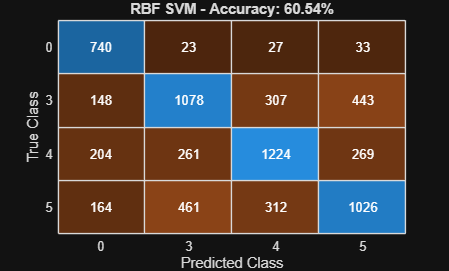


figure;
confusionchart(testLbl, pred);
title(sprintf('RBF SVM - Accuracy: %.2f%%', acc));

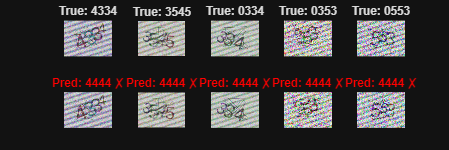


%% 7) Visa exempel på predictions (hela captcha via 4 segment) - på ORIGINALBILDER
figure('Position', [100 100 1200 400]);
numExamples = min(5, numel(allImages));

for i = 1:numExamples
    subplot(2, numExamples, i);
    imshow(allImages{i});
    title(sprintf('True: %s', allLabels{i}));

    img = allImages{i};

    if size(img, 3) == 3
        img_gray = rgb2gray(img);
    else
        img_gray = img;
    end
    img_gray = medfilt2(img_gray, [3 3]);

    width = size(img_gray, 2);
    digitWidth = floor(width / 4);

    predicted = '';

    for j = 1:4
        x_start = (j-1) * digitWidth + 1;
        x_end   = min(j * digitWidth, width);

        digitImg = img_gray(:, x_start:x_end);
        digitImg = imresize(digitImg, [28 28]);

        hogFeat = extractHOGFeatures(digitImg, 'CellSize', [7 7]);
        pixFeat = double(digitImg(:))';
        pixFeat = pixFeat(1:4:end) / 255;

        features = [hogFeat, pixFeat];
        digit = predict(svm_rbf, features);

        predicted = [predicted, num2str(digit)];
    end

    subplot(2, numExamples, numExamples + i);
    imshow(allImages{i});

    if strcmp(predicted, allLabels{i})
        title(sprintf('Pred: %s ✓', predicted), 'Color', 'green');
    else
        title(sprintf('Pred: %s ✗', predicted), 'Color', 'red');
    end
end


%% 8) Spara modellen
save('captcha_svm_rbf_method2_augmented.mat', 'svm_rbf');
fprintf('\nRBF-modell sparad: captcha_svm_rbf_method2_augmented.mat\n');


RBF-modell sparad: captcha_svm_rbf_method2_augmented.mat



%% 9) Snabb användning (exempel)
fprintf('\n=== Använd modellen så här: ===\n');


=== Använd modellen så här: ===


fprintf('load(''captcha_svm_rbf_method2_augmented.mat'');\n');

load('captcha_svm_rbf_method2_augmented.mat');


fprintf('img = imread(''test_captcha.png'');\n');

img = imread('test_captcha.png');


fprintf('%% preprocess + dela i 4 + features + predict (se kod i sektion 7)\n');

% preprocess + dela i 4 + features + predict (se kod i sektion 7)


trainPath = 'C:\Users\dbvol\MATLAB Drive\IIA_group_13\Train';

%% 1) Läs labels.txt
fid = fopen(fullfile(trainPath, 'labels.txt'), 'r');
if fid == -1
    error('Kunde inte öppna labels.txt');
end
labelData = textscan(fid, '%s', 'Delimiter', '\n');
fclose(fid);
labelData = labelData{1};

%% 2) Ladda bilder + labels
allImages = {};
allLabels = {};

for i = 1:length(labelData)
    line = strtrim(labelData{i});
    if isempty(line), continue; end

    parts = strsplit(line, ',');
    if numel(parts) >= 5
        fileNum = strtrim(parts{1});
        digits = strcat(strtrim(parts{2}), strtrim(parts{3}), strtrim(parts{4}), strtrim(parts{5}));
        filename = sprintf('captcha_%s.png', fileNum);

        imgPath = fullfile(trainPath, filename);
        if exist(imgPath, 'file')
            allImages{end+1} = imread(imgPath);
            allLabels{end+1} = digits;
        end
    end
end

fprintf('Laddade %d bilder\n', numel(allLabels));

Laddade 1200 bilder



%% 3) Train/Test split (på CAPTCHA-bilder, INNAN augmentation)
cvImg = cvpartition(numel(allImages), 'HoldOut', 0.2);

trainImages = allImages(training(cvImg));
trainLabels = allLabels(training(cvImg));

testImages  = allImages(test(cvImg));
testLabels  = allLabels(test(cvImg));

fprintf('Train captchas: %d | Test captchas: %d\n', numel(trainImages), numel(testImages));

Train captchas: 960 | Test captchas: 240



%% 4) Metod 2: Segmentering + Augmentation (ENDAST TRAIN)
fprintf('\n=== Metod 2: Segmentering + Rotation Augmentation (endast train) ===\n');


=== Metod 2: Segmentering + Rotation Augmentation (endast train) ===



angles = [-10, -7, -5, -2, 2, 5, 7, 10];

trainDigitImages = {};
trainDigitLabels = [];

for i = 1:length(trainImages)
    img_orig = trainImages{i};
    label = trainLabels{i};

    % original + roterade (endast train)
    augmentedImages = cell(1, 1 + numel(angles));
    augmentedImages{1} = img_orig;

    for a = 1:numel(angles)
        augmentedImages{1+a} = imrotate(img_orig, angles(a), 'bilinear', 'crop');
    end

    for k = 1:numel(augmentedImages)
        img = augmentedImages{k};

        if size(img, 3) == 3
            img_gray = rgb2gray(img);
        else
            img_gray = img;
        end

        % Samma preprocessing som du vill ha i inference
        img_gray = medfilt2(img_gray, [3 3]);

        % Segmentering: 4 lika delar
        width = size(img_gray, 2);
        digitWidth = floor(width / 4);

        for j = 1:4
            x_start = (j-1) * digitWidth + 1;
            x_end   = min(j * digitWidth, width);

            digitImg = img_gray(:, x_start:x_end);
            digitImg = imresize(digitImg, [28 28]);

            trainDigitImages{end+1} = digitImg;
            trainDigitLabels(end+1) = str2double(label(j));
        end
    end
end

fprintf('Train siffror: %d (inkl augmentation)\n', numel(trainDigitLabels));

Train siffror: 34560 (inkl augmentation)



%% 5) Bygg TEST-digits (INGEN augmentation)
testDigitImages = {};
testDigitLabels = [];

for i = 1:length(testImages)
    img = testImages{i};
    label = testLabels{i};

    if size(img, 3) == 3
        img_gray = rgb2gray(img);
    else
        img_gray = img;
    end

    % Samma preprocessing som train (men ingen rotation)
    img_gray = medfilt2(img_gray, [3 3]);

    width = size(img_gray, 2);
    digitWidth = floor(width / 4);

    for j = 1:4
        x_start = (j-1) * digitWidth + 1;
        x_end   = min(j * digitWidth, width);

        digitImg = img_gray(:, x_start:x_end);
        digitImg = imresize(digitImg, [28 28]);

        testDigitImages{end+1} = digitImg;
        testDigitLabels(end+1) = str2double(label(j));
    end
end

fprintf('Test siffror: %d (utan augmentation)\n', numel(testDigitLabels));

Test siffror: 960 (utan augmentation)



%% 6) Features (HOG + decimerade pixlar) för TRAIN
fprintf('\nExtraherar features...\n');


Extraherar features...



trainFeat = [];
for i = 1:numel(trainDigitImages)
    digitImg = trainDigitImages{i};

    hogFeat = extractHOGFeatures(digitImg, 'CellSize', [7 7]);
    pixFeat = double(digitImg(:))';
    pixFeat = pixFeat(1:4:end) / 255;

    features = [hogFeat, pixFeat];

    if i == 1
        trainFeat = zeros(numel(trainDigitImages), numel(features));
    end
    trainFeat(i, :) = features;
end
trainLbl = trainDigitLabels(:);

%% 7) Features för TEST
testFeat = [];
for i = 1:numel(testDigitImages)
    digitImg = testDigitImages{i};

    hogFeat = extractHOGFeatures(digitImg, 'CellSize', [7 7]);
    pixFeat = double(digitImg(:))';
    pixFeat = pixFeat(1:4:end) / 255;

    features = [hogFeat, pixFeat];

    if i == 1
        testFeat = zeros(numel(testDigitImages), numel(features));
    end
    testFeat(i, :) = features;
end
testLbl = testDigitLabels(:);

%% 8) Träna RBF SVM (ECOC) och utvärdera på TEST (utan rotation)
fprintf('\nTränar RBF SVM...\n');


Tränar RBF SVM...


t = templateSVM('KernelFunction', 'rbf', 'KernelScale', 'auto', 'Standardize', true);
svm_rbf = fitcecoc(trainFeat, trainLbl, 'Learners', t);

pred = predict(svm_rbf, testFeat);
acc = mean(pred == testLbl) * 100;

fprintf('Accuracy (RBF SVM, test utan augmentation): %.2f%%\n', acc);

Accuracy (RBF SVM, test utan augmentation): 54.17%


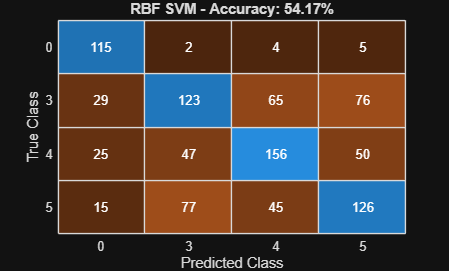


figure;
confusionchart(testLbl, pred);
title(sprintf('RBF SVM - Accuracy: %.2f%%', acc));

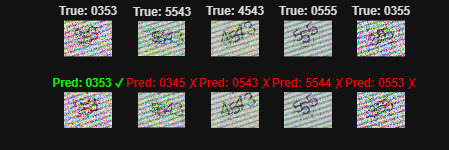


%% 9) Visa exempel på predictions (hela captcha) - på TEST ORIGINAL (men preprocessat)
figure('Position', [100 100 1200 400]);
numExamples = min(5, numel(testImages));

for i = 1:numExamples
    subplot(2, numExamples, i);
    imshow(testImages{i});
    title(sprintf('True: %s', testLabels{i}));

    img = testImages{i};

    if size(img, 3) == 3
        img_gray = rgb2gray(img);
    else
        img_gray = img;
    end

    % samma preprocess som i train/test (ingen rotation)
    img_gray = medfilt2(img_gray, [3 3]);

    width = size(img_gray, 2);
    digitWidth = floor(width / 4);

    predicted = '';

    for j = 1:4
        x_start = (j-1) * digitWidth + 1;
        x_end   = min(j * digitWidth, width);

        digitImg = img_gray(:, x_start:x_end);
        digitImg = imresize(digitImg, [28 28]);

        hogFeat = extractHOGFeatures(digitImg, 'CellSize', [7 7]);
        pixFeat = double(digitImg(:))';
        pixFeat = pixFeat(1:4:end) / 255;

        features = [hogFeat, pixFeat];
        digit = predict(svm_rbf, features);

        predicted = [predicted, num2str(digit)];
    end

    subplot(2, numExamples, numExamples + i);
    imshow(testImages{i});

    if strcmp(predicted, testLabels{i})
        title(sprintf('Pred: %s ✓', predicted), 'Color', 'green');
    else
        title(sprintf('Pred: %s ✗', predicted), 'Color', 'red');
    end
end


%% 10) Spara modellen
save('captcha_svm_rbf_method2_augmented_trainonly.mat', 'svm_rbf');
fprintf('\nRBF-modell sparad: captcha_svm_rbf_method2_augmented_trainonly.mat\n');


RBF-modell sparad: captcha_svm_rbf_method2_augmented_trainonly.mat



%% Metod 1 (NY): Klassificera HELA CAPTCHA med HOG + RBF SVM + train-only rotation
clear; clc;

%% 0) Sökväg
trainPath = 'C:\Users\dbvol\MATLAB Drive\IIA_group_13\Train';

%% 1) Läs labels.txt
fid = fopen(fullfile(trainPath, 'labels.txt'), 'r');
if fid == -1
    error('Kunde inte öppna labels.txt');
end
labelData = textscan(fid, '%s', 'Delimiter', '\n');
fclose(fid);
labelData = labelData{1};

%% 2) Ladda bilder + labels (hela strängen som label)
allImages = {};
allLabels = {};

for i = 1:length(labelData)
    line = strtrim(labelData{i});
    if isempty(line), continue; end

    parts = strsplit(line, ',');
    if numel(parts) >= 5
        fileNum = strtrim(parts{1});
        digits = strcat(strtrim(parts{2}), strtrim(parts{3}), strtrim(parts{4}), strtrim(parts{5}));
        filename = sprintf('captcha_%s.png', fileNum);

        imgPath = fullfile(trainPath, filename);
        if exist(imgPath, 'file')
            allImages{end+1} = imread(imgPath);
            allLabels{end+1} = digits;  % t.ex. '3045'
        end
    end
end

fprintf('Laddade %d bilder\n', numel(allLabels));

Laddade 1200 bilder



%% 3) Train/Test split på CAPTCHA-bilder (innan augmentation)
cvImg = cvpartition(numel(allImages), 'HoldOut', 0.2);

trainImages = allImages(training(cvImg));
trainLabels = allLabels(training(cvImg));

testImages  = allImages(test(cvImg));
testLabels  = allLabels(test(cvImg));

fprintf('Train captchas: %d | Test captchas: %d\n', numel(trainImages), numel(testImages));

Train captchas: 960 | Test captchas: 240



%% 4) Bygg TRAIN features (med augmentation)
fprintf('\n=== Metod 1: Hela captcha + rotation augmentation (endast train) ===\n');


=== Metod 1: Hela captcha + rotation augmentation (endast train) ===



angles = [-10, -7, -5, -2, 2, 5, 7, 10];   % augmentation-vinklar
targetSize = [50 160];                    % justera vid behov

trainFeat = [];
trainLbl  = {};

row = 0;

for i = 1:numel(trainImages)
    img_orig = trainImages{i};
    lbl = trainLabels{i};

    % original + roterade (endast train)
    augmented = cell(1, 1 + numel(angles));
    augmented{1} = img_orig;

    for a = 1:numel(angles)
        % OBS: 'crop' kan kapa lite. Om du vill undvika kapning:
        % rot = imrotate(img_orig, angles(a), 'bilinear', 'loose');
        % rot = imresize(rot, [size(img_orig,1) size(img_orig,2)]);
        rot = imrotate(img_orig, angles(a), 'bilinear', 'crop');
        augmented{1+a} = rot;
    end

    for k = 1:numel(augmented)
        img = augmented{k};

        % --- Preprocess (samma som du vill ha vid inference) ---
        if size(img,3) == 3
            img_gray = rgb2gray(img);
        else
            img_gray = img;
        end
        img_gray = medfilt2(img_gray, [3 3]);

        % Resize
        img_rs = imresize(img_gray, targetSize);

        % --- Features: HOG över HELA bilden ---
        hog = extractHOGFeatures(img_rs, 'CellSize', [8 8]);

        % (valfritt) lite decimerade pixlar kan hjälpa, men börja med bara HOG
        % pix = double(img_rs(:))';
        % pix = pix(1:8:end) / 255;
        % feat = [hog, pix];
        feat = hog;

        row = row + 1;
        if row == 1
            trainFeat = zeros(numel(trainImages) * (1+numel(angles)), numel(feat));
        end
        trainFeat(row,:) = feat;
        trainLbl{row,1}  = lbl;
    end
end

% trimma ifall prealloc blev för stor pga edgecases
trainFeat = trainFeat(1:row,:);
trainLbl  = trainLbl(1:row,:);

%% 5) Bygg TEST features (ingen augmentation)
testFeat = [];
testLbl  = testLabels(:);

for i = 1:numel(testImages)
    img = testImages{i};

    if size(img,3) == 3
        img_gray = rgb2gray(img);
    else
        img_gray = img;
    end
    img_gray = medfilt2(img_gray, [3 3]);

    img_rs = imresize(img_gray, targetSize);

    hog = extractHOGFeatures(img_rs, 'CellSize', [8 8]);
    feat = hog;

    if i == 1
        testFeat = zeros(numel(testImages), numel(feat));
    end
    testFeat(i,:) = feat;
end

%% 6) Träna RBF SVM (ECOC) på HELA strängen och utvärdera
fprintf('\nTränar RBF SVM (hela captchan)...\n');


Tränar RBF SVM (hela captchan)...


t = templateSVM('KernelFunction','rbf','KernelScale','auto','Standardize',true);
svm_full = fitcecoc(trainFeat, trainLbl, 'Learners', t);

pred = predict(svm_full, testFeat);

acc_full = mean(strcmp(pred, testLbl)) * 100;
fprintf('Accuracy (hela captcha, test utan augmentation): %.2f%%\n', acc_full);

Accuracy (hela captcha, test utan augmentation): 4.17%


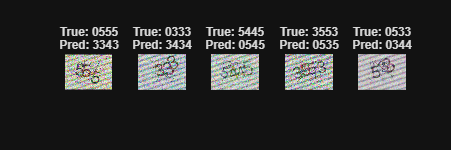


%% 7) Visa exempel på predictions
figure('Position', [100 100 1200 400]);
numExamples = min(5, numel(testImages));

for i = 1:numExamples
    subplot(1, numExamples, i);
    imshow(testImages{i});
    title(sprintf('True: %s\nPred: %s', testLbl{i}, pred{i}));
end


%% 8) Spara modellen
save('captcha_svm_rbf_method1_fullstring.mat', 'svm_full', 'targetSize');

fprintf('\nModell sparad: captcha_svm_rbf_method1_fullstring.mat\n');


Modell sparad: captcha_svm_rbf_method1_fullstring.mat


%% Method 1 (Whole CAPTCHA) + AdaBoost (train-only rotation augmentation)
clear; clc;

%% 0) Path
trainPath = 'C:\Users\dbvol\MATLAB Drive\IIA_group_13\Train';

%% 1) Read labels.txt
fid = fopen(fullfile(trainPath, 'labels.txt'), 'r');
if fid == -1, error('Could not open labels.txt'); end
labelData = textscan(fid, '%s', 'Delimiter', '\n');
fclose(fid);
labelData = labelData{1};

%% 2) Load images + string labels (e.g. '3045')
allImages = {};
allLabels = {};

for i = 1:numel(labelData)
    line = strtrim(labelData{i});
    if isempty(line), continue; end

    parts = strsplit(line, ',');
    if numel(parts) >= 5
        fileNum = strtrim(parts{1});
        digits = strcat(strtrim(parts{2}), strtrim(parts{3}), strtrim(parts{4}), strtrim(parts{5}));
        filename = sprintf('captcha_%s.png', fileNum);

        imgPath = fullfile(trainPath, filename);
        if exist(imgPath, 'file')
            allImages{end+1} = imread(imgPath);
            allLabels{end+1} = digits;
        end
    end
end

fprintf('Loaded %d images\n', numel(allLabels));

Loaded 1200 images



%% 3) Train/Test split BEFORE augmentation
cvImg = cvpartition(numel(allImages), 'HoldOut', 0.2);
trainImages = allImages(training(cvImg));
trainLabels = allLabels(training(cvImg));
testImages  = allImages(test(cvImg));
testLabels  = allLabels(test(cvImg));

fprintf('Train captchas: %d | Test captchas: %d\n', numel(trainImages), numel(testImages));

Train captchas: 960 | Test captchas: 240



%% 4) Build TRAIN features (HOG) with train-only rotation augmentation
angles = [-10, -7, -5, -2, 2, 5, 7, 10];  % train-only aug
targetSize = [50 160];                   % resize for whole captcha

trainFeat = [];
trainLbl  = {};
row = 0;

for i = 1:numel(trainImages)
    img_orig = trainImages{i};
    lbl = trainLabels{i};

    augmented = cell(1, 1 + numel(angles));
    augmented{1} = img_orig;

    for a = 1:numel(angles)
        % Safer than 'crop' (avoids cutting digits): loose + resize back
        rot = imrotate(img_orig, angles(a), 'bilinear', 'loose');
        rot = imresize(rot, [size(img_orig,1), size(img_orig,2)]);
        augmented{1+a} = rot;
    end

    for k = 1:numel(augmented)
        img = augmented{k};

        % --- preprocess (keep SAME for train & test) ---
        if size(img,3) == 3, img_gray = rgb2gray(img); else, img_gray = img; end
        img_gray = medfilt2(img_gray, [3 3]);

        % Optional: uncomment to help with noisy backgrounds
        % img_bw = imbinarize(img_gray,'adaptive','ForegroundPolarity','dark','Sensitivity',0.55);
        % img_bw = bwareaopen(img_bw, 20);
        % img_bw = imclose(img_bw, strel('disk',1));
        % img_gray = img_bw;

        img_rs = imresize(img_gray, targetSize);

        hog = extractHOGFeatures(img_rs, 'CellSize', [8 8]);  % try [6 6] or [4 4] too
        feat = hog;

        row = row + 1;
        if row == 1
            trainFeat = zeros(numel(trainImages) * (1+numel(angles)), numel(feat));
        end
        trainFeat(row,:) = feat;
        trainLbl{row,1}  = lbl;
    end
end

trainFeat = trainFeat(1:row,:);
trainLbl  = trainLbl(1:row,:);

%% 5) Build TEST features (NO augmentation)
testFeat = [];
for i = 1:numel(testImages)
    img = testImages{i};

    if size(img,3) == 3, img_gray = rgb2gray(img); else, img_gray = img; end
    img_gray = medfilt2(img_gray, [3 3]);

    % Optional: if you used binarization on train, also use it here
    % img_bw = imbinarize(img_gray,'adaptive','ForegroundPolarity','dark','Sensitivity',0.55);
    % img_bw = bwareaopen(img_bw, 20);
    % img_bw = imclose(img_bw, strel('disk',1));
    % img_gray = img_bw;

    img_rs = imresize(img_gray, targetSize);

    hog = extractHOGFeatures(img_rs, 'CellSize', [8 8]);
    feat = hog;

    if i == 1
        testFeat = zeros(numel(testImages), numel(feat));
    end
    testFeat(i,:) = feat;
end

testLbl = testLabels(:);

%% 6) Train AdaBoost (AdaBoostM2) and evaluate
fprintf('\nTraining AdaBoost (AdaBoostM2)...\n');


Training AdaBoost (AdaBoostM2)...



% Weak learner = shallow decision trees
tTree = templateTree('MaxNumSplits', 20);  % try 10, 20, 50

% AdaBoostM2 supports multiclass
ens = fitcensemble(trainFeat, trainLbl, ...
    'Method', 'AdaBoostM2', ...
    'Learners', tTree, ...
    'NumLearningCycles', 300, ...
    'LearnRate', 0.1);

pred = predict(ens, testFeat);
acc = mean(strcmp(pred, testLbl)) * 100;

fprintf('Accuracy (whole captcha, test no-aug): %.2f%%\n', acc);

%% 7) Show a few predictions
figure('Position',[100 100 1200 400]);
numExamples = min(8, numel(testImages));
for i = 1:numExamples
    subplot(2, ceil(numExamples/2), i);
    imshow(testImages{i});
    title(sprintf('True: %s\nPred: %s', testLbl{i}, pred{i}));
end

%% 8) Save model
save('captcha_adaboost_method1_fullstring.mat', 'ens', 'targetSize');
fprintf('\nSaved: captcha_adaboost_method1_fullstring.mat\n');
